# **InverseGaudermannGD**

[Inverse Gudermannian function](https://en.wikipedia.org/wiki/Gudermannian_function) (inverse hyperbolic amplitude function)

## Definition


$${\textrm{gd}}^{-1} \;x\equiv \int_0^x \frac{\textrm{dt}}{\mathrm{cos}\;t}={\mathrm{sinh}}^{-1} \left(\mathrm{tan}\;x\right)$$


Domain: $-\pi /2\le x\le \pi /2$. For the specified domain, the  codomain is the set of real numbers.

Special values:

   ${\textrm{gd}}^{-1} \;0=0$,   ${\textrm{gd}}^{-1} \left(\pm \pi /2\right)=\pm \infty$

Identities:


$${\textrm{gd}}^{-1} \;x=\mathrm{ln}\;\mathrm{tan}\left(\frac{x}{2}+\frac{\pi }{4}\right)$$


## Syntax

Y = InverseGudermannGD(X)

y = igd(x)

## Description

**Y = InverseGudermannGD(X)** returns the value of the inverse Gudermannian function ${\textrm{gd}}^{-1} \;x$ for each element of the array  X .  X must be real array or scalar. **InverseGudermannGD** is the wrapper function which calls the functions **igd** element-wise via the function **ufun1**.

**y = igd(x)** calculate the value of the  the the inverse Gudermannian function ${\textrm{gd}}^{-1} \;x$  for the  x. It is assumed that  x is real scalars without check. y is NaN if x is invalid or convergence failed.

## Precision

## **Numerical Examples**

**Scalar input**

format long
x = 1/2; 
[igd(x), InverseGudermannGD(x)]

ans =    0.522238103278440   0.522238103278440


Accuracy. 

fprintf('%.16g\n',igd(1)) 

1.226191170883517


% Maple 1.226191170883517_07

Special values

igd(0)

ans = 0

igd(-pi/2)

ans = -Inf

igd(pi/2)

ans = Inf

Identities

x = 1/4;
disp(igd(x)-log(tan(x/2+pi/4)))

     0



**Vector input**

x=pi*[1e-6 1/2 1/3 1e-20];
disp(InverseGudermannGD(x)-log(tan(x/2 + pi/4*ones(size(x)))))

   1.0e-15 *

   0.105865565879631                 Inf   0.444089209850063   0.111053718389052



**Matrix input**

x=pi*[-1/12 1/3 1/4; 1/24 -1/3 -1/4];
disp(InverseGudermannGD(x)-log(tan(x/2 + pi/4*ones(size(x)))))

   1.0e-15 *

  -0.055511151231258   0.444089209850063                   0
  -0.083266726846887   0.222044604925031   0.111022302462516



## **Plot**

**Example 1**

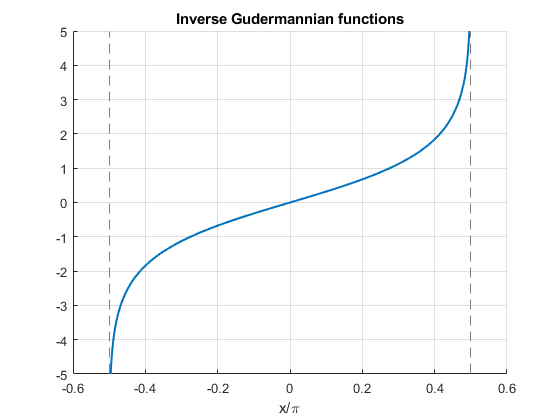

figure
hold on
fplot(@(x) InverseGudermannGD(x*pi),1.1*[-1/2 1/2],'LineWidth',1.5)
title('Inverse Gudermannian functions')
xlabel('x/\pi')
grid on

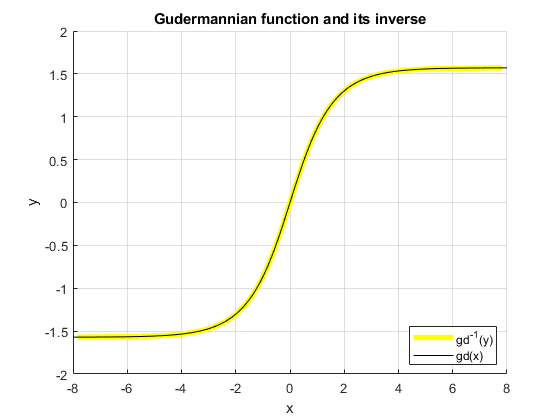

figure
hold on
x=-8:0.01:8;
plot(InverseGudermannGD(x),x,'LineWidth',4,'Color','y')
plot(x,GudermannGD(x),'LineWidth',0.5,'Color','k')
title('Gudermannian function and its inverse')
legend('gd^{-1}(y)','gd(x)','Location','best')
xlabel('x')
ylabel('y')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

## **References**

## See Also